#  Example double rotation

The double rotation algorithm is used to correct the tilt angle of one anemometer

 Notations:

 x: horizontal axis parallel to the wind direction

 y: horizontal axis normal to the wind direction

 z: vertical axis

 u: along-wind velocity component

 v: across-wind velocity component

 w: vertical-wind velocity component

##  Generate tilted wind velocity records

clearvars;close all;clc;
 % load simlated wind velocities
load('data.mat','u','v','w','t')
[M,N]=size(u); 

yaw  = 20; % yaw angle (horizontal plane, between u and v)
elev = 3; % elevation angle (vertical plane, between w and u)
incl = 2; % inclination angle (vertical plane, between w and v)

R1 = [cosd(yaw),-sind(yaw),0;sind(yaw),cosd(yaw),0;0,0,1]; % matrix rotation around axis z
R2 = [cosd(elev),0,-sind(elev);0,1,0;sind(elev),0,cosd(elev)]; % matrix rotation around axis zy
R3 = [1,0,0; 0,cosd(incl),-sind(incl);0,sind(incl),cosd(incl)]; % matrix rotation around axis x

A = R1*R2*R3;  % 3D rotation matrix

% Construction of tilted velocity component
u_tilted = zeros(size(u));
v_tilted = zeros(size(u));
w_tilted = zeros(size(u));
for ii=1:M,
    dummy = A\[u(ii,:);v(ii,:);w(ii,:)];
    u_tilted(ii,:) = dummy(1,:);
    v_tilted(ii,:) = dummy(2,:);
    w_tilted(ii,:) = dummy(3,:);
end

##  Retrieveal of u, v and w

tic
[u3,v3,w3] = tiltCorrection(u_tilted,v_tilted,w_tilted,'method','rot2');
toc

Elapsed time is 0.050166 seconds.


##  Verification w component

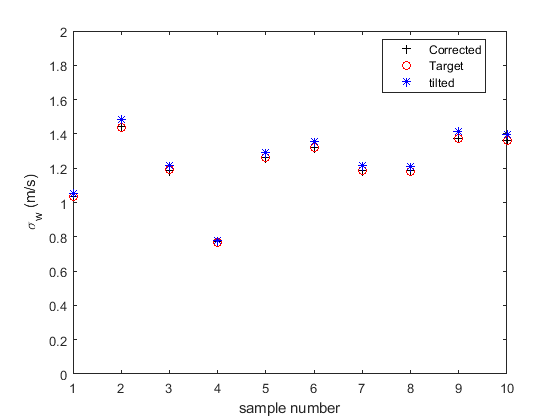


clf;close all;
figure
plot(abs(mean(w3,2)),'k+');
hold on;
plot(abs(mean(w,2)),'ro')
plot(abs(mean(w_tilted,2)),'b*')
legend('Corrected','Target','original','location','best')
xlabel('sample number')
ylabel('$\overline{w}$ (m/s)','interpreter','latex')
set(gcf,'color','w')


figure
plot(abs(std(w3,0,2)),'k+');
hold on;
plot(abs(std(w,0,2)),'ro')
plot(abs(std(w_tilted,0,2)),'b*')
legend('Corrected','Target','tilted','location','best')
ylim([0,2])
xlabel('sample number')
ylabel('\sigma_w (m/s)')
set(gcf,'color','w')

## Verification v component

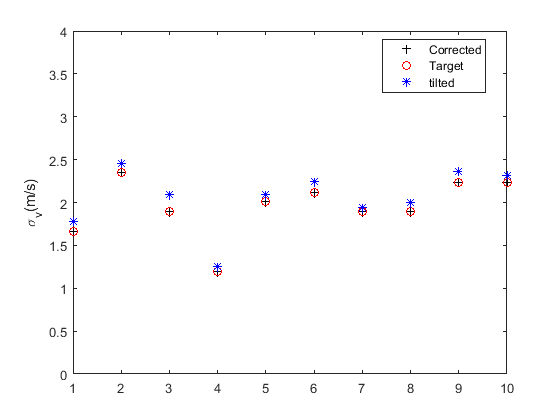


clf;close all;
figure
plot(abs(mean(v3,2)),'k+');
hold on;
plot(abs(mean(v,2)),'ro')
plot(abs(mean(v_tilted,2)),'b*')
legend('Corrected','Target','tilted','location','best')
ylim([0,20])
ylabel('$\overline{v}$ (m/s)','interpreter','latex')
set(gcf,'color','w')

figure
plot(std(v3,0,2),'k+');
hold on;
plot(std(v,0,2),'ro')
plot(std(v_tilted,0,2),'b*')
legend('Corrected','Target','tilted','location','best')
ylim([0,4])
ylabel('\sigma_v(m/s)')
set(gcf,'color','w')

##  Verification u component

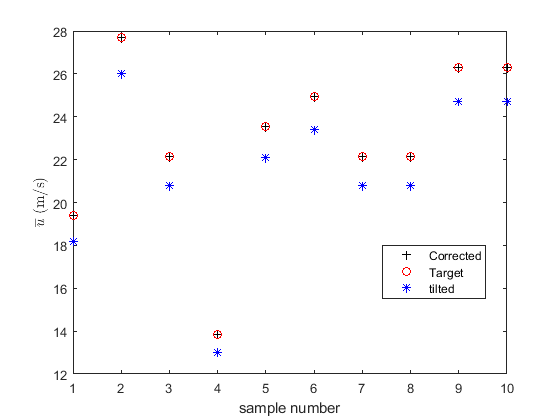

clf;close all;
figure

plot(abs(mean(u3,2)),'k+');
hold on;
plot(abs(mean(u,2)),'ro')
plot(abs(mean(u_tilted,2)),'b*')
legend('Corrected','Target','tilted','location','best')
xlabel('sample number')
ylabel('$\overline{u}$ (m/s)','interpreter','latex')
set(gcf,'color','w')

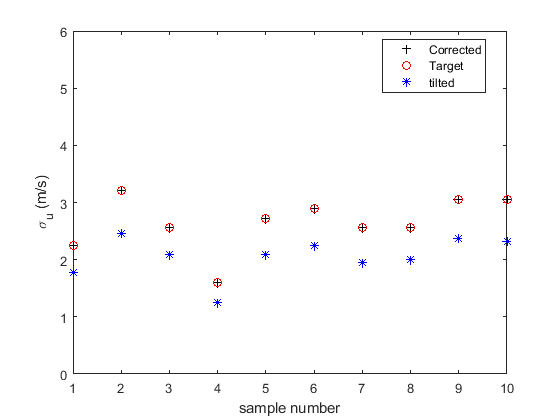


figure
plot((std(u3,0,2)),'k+');
hold on;
plot((std(u,0,2)),'ro')
plot(std(v_tilted,0,2),'b*')
legend('Corrected','Target','tilted','location','best')
xlabel('sample number')
ylabel('\sigma_u (m/s)')
set(gcf,'color','w')
ylim([0,6])